addpath(genpath('functions')); % add custome functions to the path

clear;
clf;
cla;
clc;

% Calculate end effector position and obtain arm configurations
[pGripper, arm1, arm2, arm3] = EndEffectorPosition(30, 45, 2);

% Plot the robotic arm system
plotSystem(arm1, arm2, arm3);

% Set the view angle for the plot
view(10, 10);


thetaStart = [0, 0, 0];      % Initial angles [Q1_start, Q2_start] in radians
thetaStop = [pi/6, pi, 2];   % Final   angles [Q1_end, Q2_end]     in radians
animationTime = 10;          % Desired animation time in seconds

% Calling the function
plotKinematics(thetaStart, thetaStop, animationTime);


thetaStart = [-8 * pi, -8 * pi/2, -1];   % Initial angles [Q1_start, Q2_start] in radians
thetaStop = [8 * pi, 8 * pi/2, 1];       % Final   angles [Q1_end, Q2_end]     in radians
animationTime = 10;                      % Desired animation time in seconds

% Calling the function
plotKinematics(thetaStart, thetaStop, animationTime);



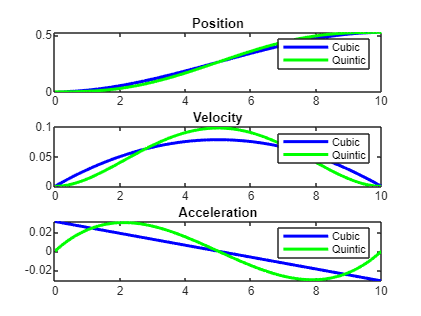

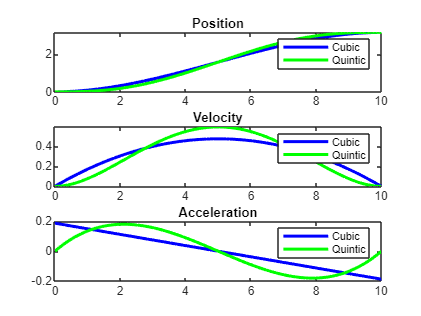

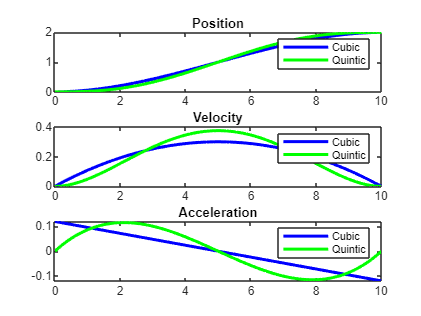


q=[0, pi/6;...
   0, pi;...
   0, 2]; 
    

T = 10;        % Timpul total pentru traiectorie (de exemplu 5 secunde)
n = 100;      % Numărul de pași (100 de puncte pentru traiectorie)


% Apelarea funcției care calculează traiectoria
% Functia va returna pozitiile, viteza si acceleratia pentru fiecare cuplu de roti

trajectoryPlanner(q, T, n);